load('nathan test 1 min.mat')
whos("Acceleration")

  Name                Size            Bytes  Class        Attributes

  Acceleration      626x3             21579  timetable              



%[Data]=ParseMatlabApp('one_min_test.mat')
[Data]=ParseMatlabApp('one_min_control.mat')

Data = struct with fields:
      Accel: [617×3 double]
    t_Accel: [617×1 double]


Data

Data = struct with fields:
      Accel: [617×3 double]
    t_Accel: [617×1 double]


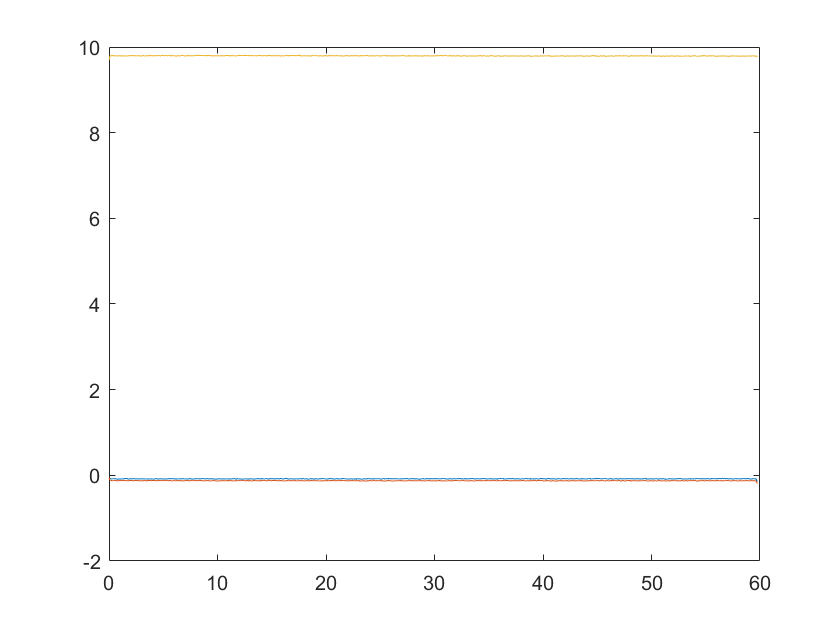

plot(Data.t_Accel,Data.Accel)

z = Data.Accel(:,3)'

z =     9.6942    9.7981    9.7938    9.7990    9.7986    9.7943    9.7885    9.8005    9.7904    9.7923    9.7957    9.7943    9.7890    9.7947    9.7933    9.7904    9.7967    9.7890    9.7876    9.7971    9.7990    9.7962    9.8000    9.7990    9.7962    9.7957    9.7899    9.7976    9.7957    9.7962    9.7909    9.7914    9.7967    9.7990    9.7904    9.7943    9.7981    9.7947    9.7981    9.7957    9.8034    9.7899    9.7976    9.7995    9.7952    9.7990    9.7938    9.8019    9.7976    9.7933


y = fft(z)

y = 	1.0e+03 *

   6.0423 + 0.0000i  -0.0001 - 0.0013i  -0.0003 - 0.0003i  -0.0004 - 0.0002i  -0.0001 - 0.0002i  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0003 + 0.0001i  -0.0002 - 0.0001i  -0.0002 - 0.0001i   0.0000 - 0.0002i  -0.0001 - 0.0001i  -0.0001 + 0.0000i  -0.0001 + 0.0002i   0.0001 - 0.0001i  -0.0000 - 0.0000i  -0.0001 - 0.0002i  -0.0002 + 0.0001i  -0.0002 - 0.0001i  -0.0002 + 0.0001i  -0.0002 + 0.0001i  -0.0000 - 0.0000i  -0.0001 - 0.0001i   0.0000 - 0.0000i   0.0001 + 0.0000i  -0.0001 + 0.0000i  -0.0002 - 0.0001i  -0.0001 + 0.0000i   0.0001 + 0.0000i   0.0000 - 0.0001i  -0.0002 - 0.0001i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0000 + 0.0001i  -0.0001 + 0.0000i  -0.0001 - 0.0001i  -0.0002 - 0.0002i  -0.0001 + 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0002 + 0.0001i  -0.0003 - 0.0001i  -0.0002 + 0.0000i  -0.0001 + 0.0001i  -0.0001 + 0.0001i  -0.0001 - 0.0001i  -0.0002 - 0.0001i  -0.0001 - 0.0000i  -0.0002 - 0.0000i  -0.0001 - 0.0000i


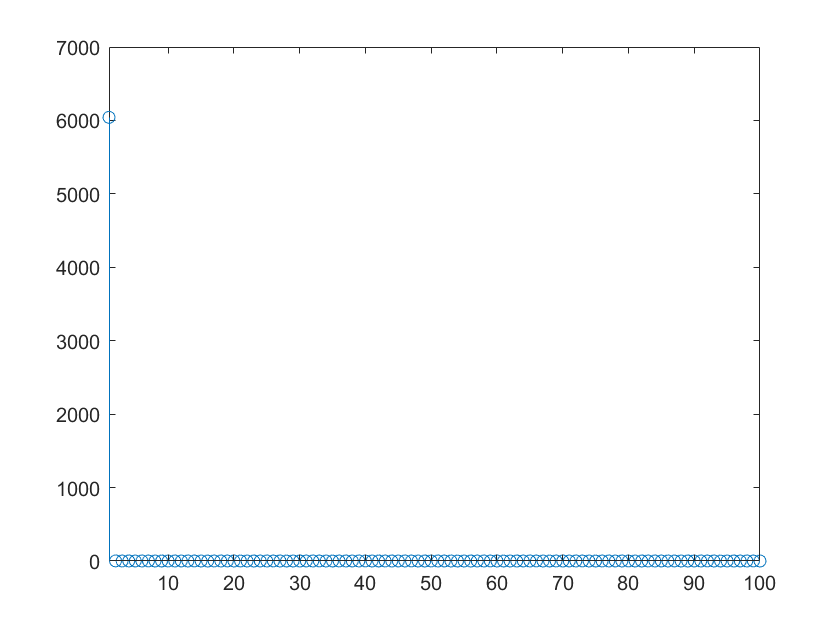

stem(abs(y))
xlim([1 100])